# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
for i = 2:length(SIDS)-1
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'}
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'}
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

typeCell =     '270'    '90'    'Null'


p =    1.0e-16 *

    0.0000
         0
    0.1021


tbl =     'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'             'Prob>F'    
    'anovaNumStims'                 [6.1036e+04]    [   3]    [        0]    [2.0345e+04]    [   50.8356]    [1.4081e-32]
    'anovaBetaSID'                  [6.7916e+06]    [   6]    [        0]    [1.1319e+06]    [2.8283e+03]    [         0]
    'anovaNumStims*anovaBetaSID'    [4.9615e+04]    [  18]    [        0]    [2.7564e+03]    [    6.8872]    [1.0210e-17]
    'Error'                         [3.6724e+06]    [9176]    [        0]    [  400.2208]              []              []
    'Total'                         [1.2500e+07]    [9203]    [        0]              []              []              []


stats =          source: 'anovan'
          resid: [9204x1 double]
         coeffs: [40x1 double]
            Rtr: [28x28 double]
       rowbasis: [28x40 double]
            dfe: 9176
            mse: 400.2208
    nullproject: [40x28 double]
          terms: [3x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [4x1 double]
     coeffnames: {40x1 cell}
           vars: [40x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


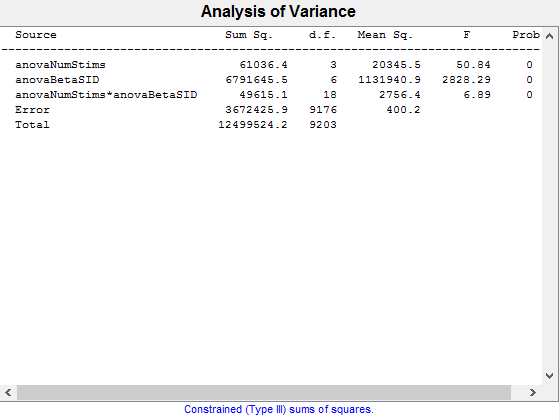

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'model','interaction','varnames',{'anovaNumStims','anovaBetaSID'})

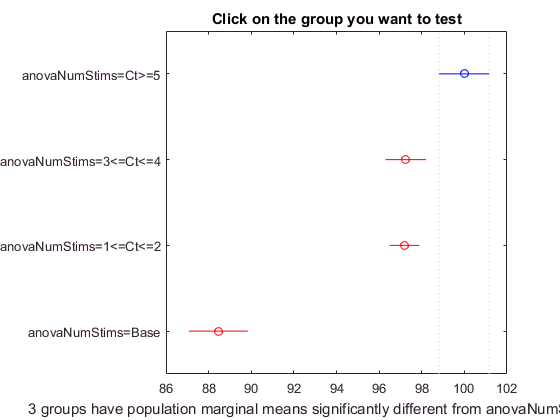

c =     1.0000    2.0000    0.5947    2.7393    4.8838    0.0057
    1.0000    3.0000    0.9238    2.8052    4.6866    0.0007
    1.0000    4.0000    9.0071   11.5344   14.0618    0.0000
    2.0000    3.0000   -1.5536    0.0659    1.6854    0.9996
    2.0000    4.0000    6.4562    8.7952   11.1341    0.0000
    3.0000    4.0000    6.6290    8.7292   10.8295    0.0000


m =    99.9879    0.6464
   97.2486    0.5282
   97.1827    0.3441
   88.4535    0.7416


h =   Figure (14: Multiple comparison of population marginal means) with properties:

      Number: 14
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


figure
[c,m,h,gnames] = multcompare(stats)

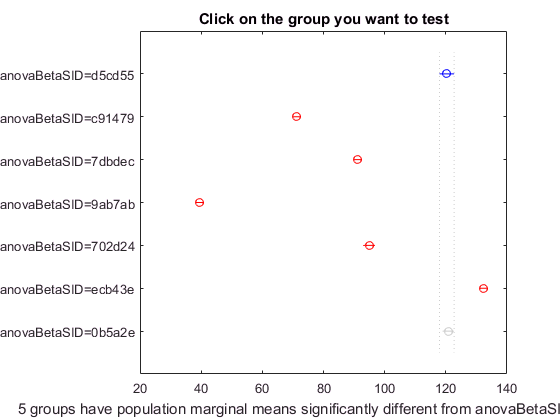

results =     1.0000    2.0000   45.4835   49.1277   52.7719    0.0000
    1.0000    3.0000   25.5524   29.2792   33.0059    0.0000
    1.0000    4.0000   77.2706   80.8464   84.4223    0.0000
    1.0000    5.0000   21.2013   25.4089   29.6165    0.0000
    1.0000    6.0000  -15.6812  -11.9550   -8.2288    0.0000
    1.0000    7.0000   -4.6010   -0.4589    3.6832    0.9999
    2.0000    3.0000  -22.3437  -19.8485  -17.3534    0.0000
    2.0000    4.0000   29.4551   31.7187   33.9823    0.0000
    2.0000    5.0000  -26.8876  -23.7188  -20.5500    0.0000
    2.0000    6.0000  -63.5770  -61.0827  -58.5884    0.0000



figure
results = multcompare(stats,'Dimension',[2])

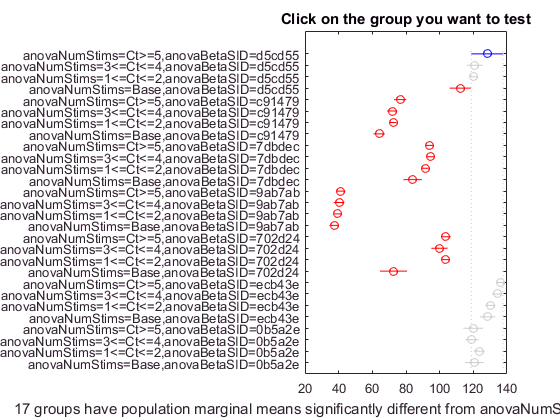

results =     1.0000    2.0000   -6.3021    7.3406   20.9833    0.9716
    1.0000    3.0000   -4.2071    8.0654   20.3379    0.7907
    1.0000    4.0000    1.4108   15.9843   30.5578    0.0134
    1.0000    5.0000   38.7006   51.6340   64.5675    0.0000
    1.0000    6.0000   43.7407   56.3640   68.9872    0.0000
    1.0000    7.0000   43.7135   55.8163   67.9191    0.0000
    1.0000    8.0000   51.2572   64.0868   76.9164    0.0000
    1.0000    9.0000   21.6782   34.0523   46.4265    0.0000
    1.0000   10.0000   21.1623   33.5967   46.0311    0.0000
    1.0000   11.0000   24.4908   36.6345   48.7783    0.0000



% figure
% results = multcompare(stats,'Dimension',[3])

figure
results = multcompare(stats,'Dimension',[1 2])